## Plot data and external control signal

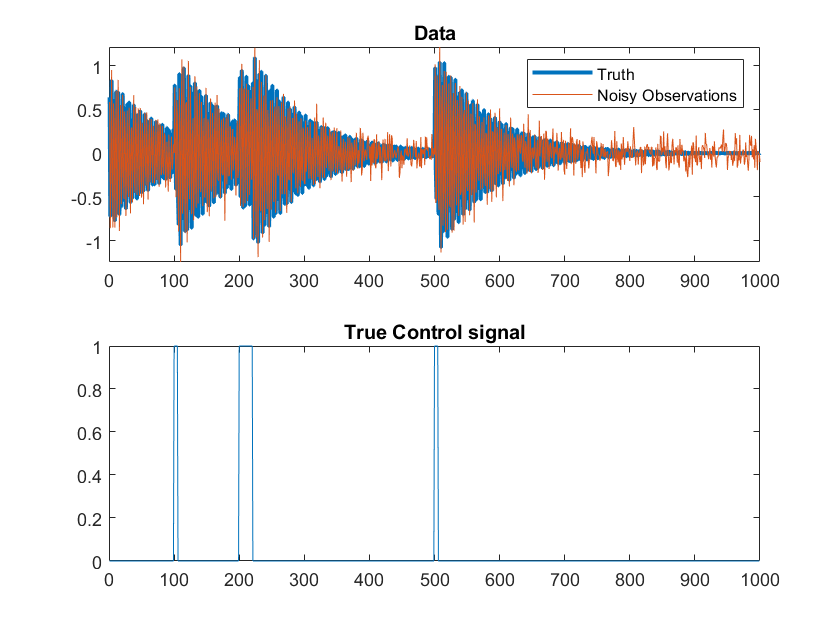

% Build example dynamics matrix
seed = 17;
n = 2;                  % Matrix size; should be even
m = 1000;               % Number of data points
eigenvalue_min = 0.95;  % Minimum eigenvalue; 1.0 = stable
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Build several random controllers
ctr_timing = [100:105, 200:220, 500:505];
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add noise
noise = 0.1;
X = X_true + noise*randn(size(X_true));

% Plot
figure;

subplot(2,1,1)
plot(1:m,X_true(1,:), 'LineWidth',2)
hold on
plot(1:m,X(1,:))
title("Data")
legend(["Truth", "Noisy Observations"])

subplot(2,1,2)
plot(1:m-1,U)
title("True Control signal")

## What to do if only 1 dimension is available?

Time delay embedding!

% We only see one dimension
X = X(1,:);

% Augment with delays
num_delays = 3;

X = time_delay_embed(X, num_delays);

## Attempt 1: Learn the control signal

% Returns a data class with control signals of increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
control_signal_path = learn_control_signals(X, settings);

All control signals are 0. Stopping early (this is nothing to worry about)



% Calculate best control signal
objective_function = 'aic';
control_signal_path.calc_best_control_signal(objective_function)

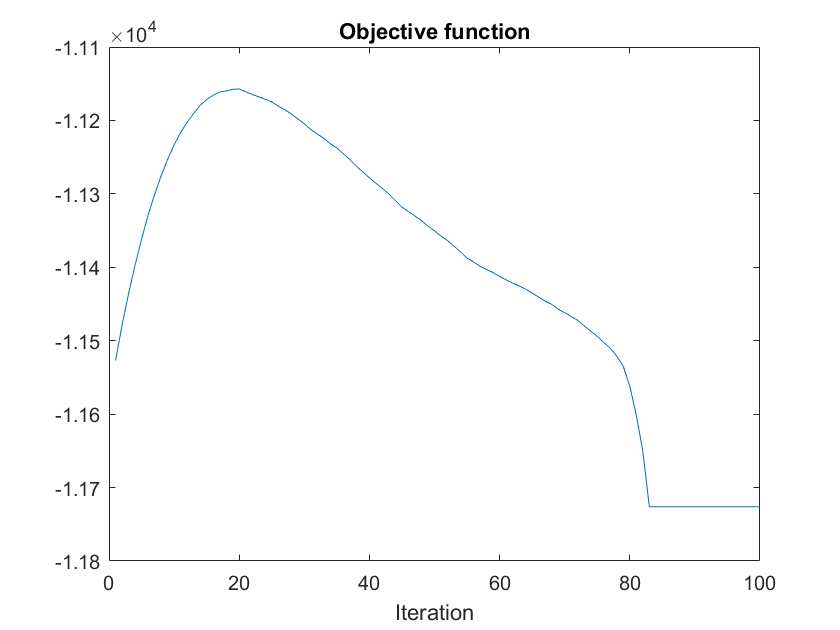


best_U = control_signal_path.U;

% Plot
objective_vals = control_signal_path.objective_values;

figure;
plot(objective_vals)
title('Objective function')
xlabel('Iteration')

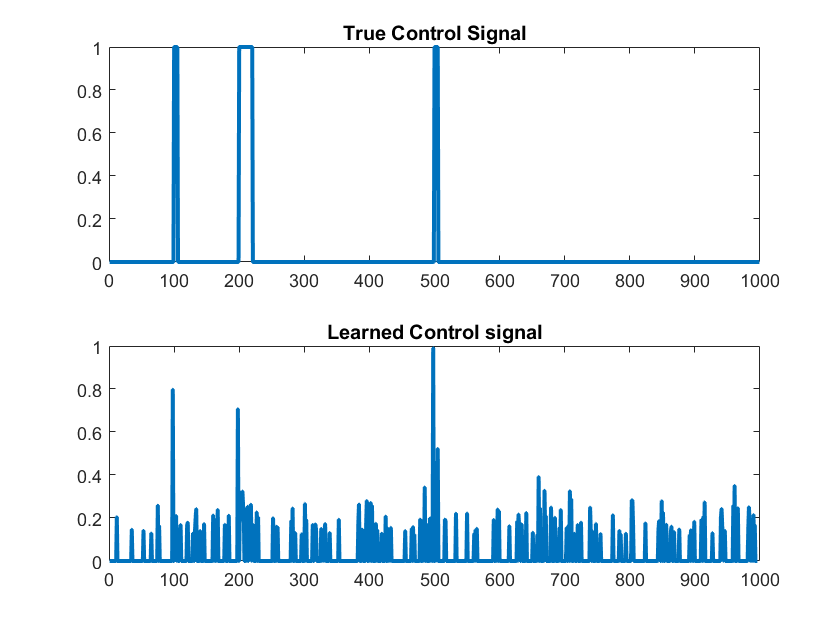


figure;
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U, 'linewidth', 2)
title("Learned Control signal")

## Attempt 2: Learn the control signal, but smooth the initialization

% Use the same base settings from before
settings.to_smooth_initialization = true;
settings.initialization_smoothing_windows = [1, 3];
control_signal_path2 = learn_control_signals(X, settings);

All control signals are 0. Stopping early (this is nothing to worry about)



% Calculate best control signal
objective_function = 'aic';
control_signal_path2.calc_best_control_signal(objective_function)

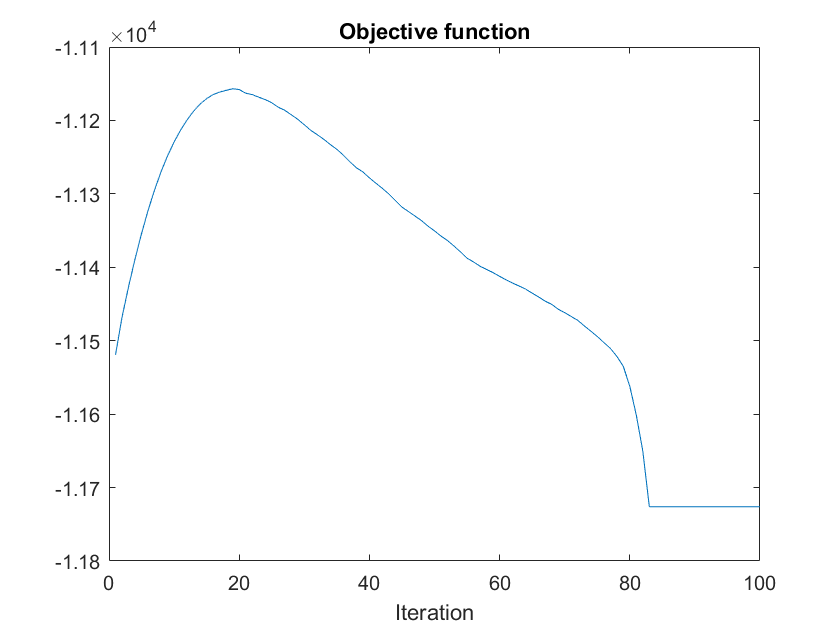


best_U2 = control_signal_path2.U;

% Plot
objective_vals = control_signal_path2.objective_values;

figure;
plot(objective_vals)
title('Objective function')
xlabel('Iteration')

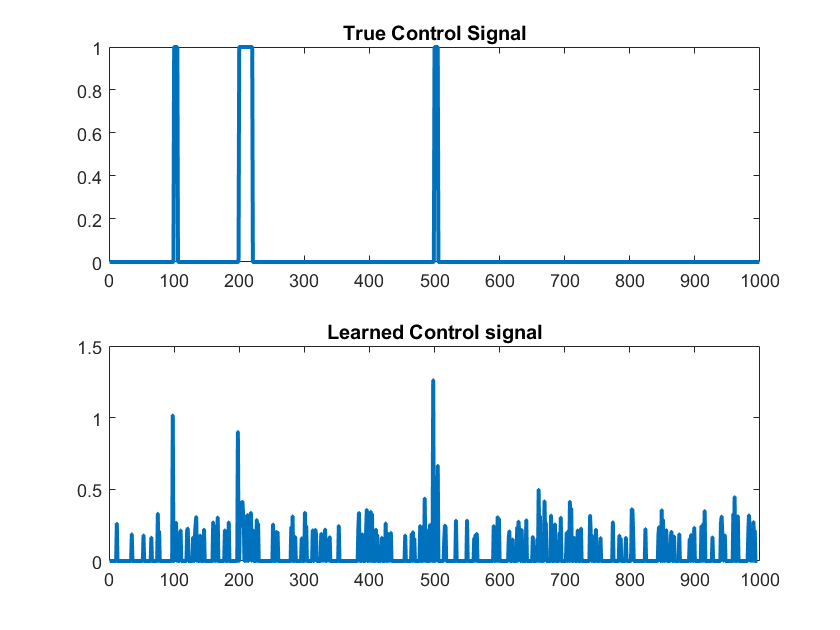


figure;
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U2, 'linewidth', 2)
title("Learned Control signal")

## Do DMDc using learned control signal

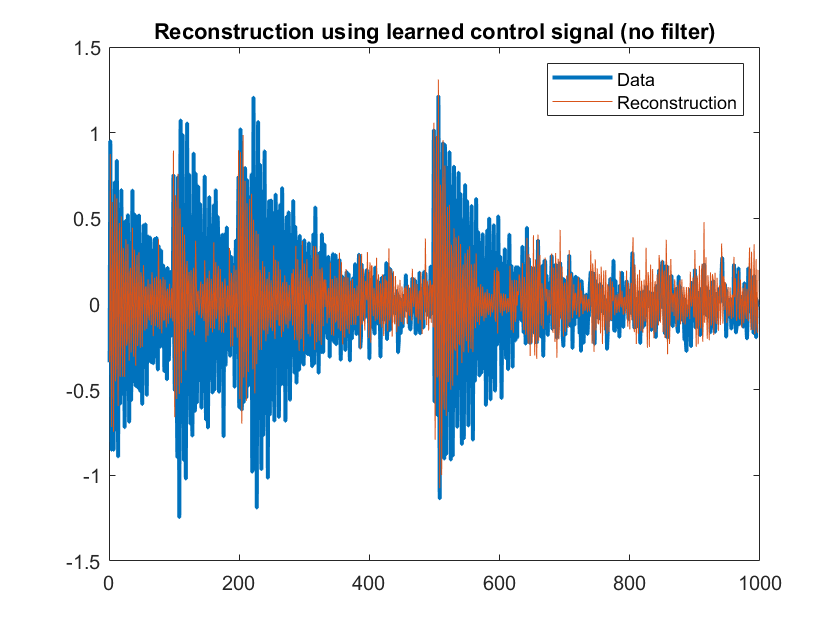

% Get learned matrices: no filtering
[best_A, best_B, learned_X] = simple_dmdc(X, best_U);
% Get learned matrices: with filtering
[best_A2, best_B2, learned_X2] = simple_dmdc(X, best_U2);

% Plot
figure;
plot(X(1,:), 'linewidth', 2)
hold on
plot(learned_X(1,:))
legend("Data", "Reconstruction")
title("Reconstruction using learned control signal (no filter)")

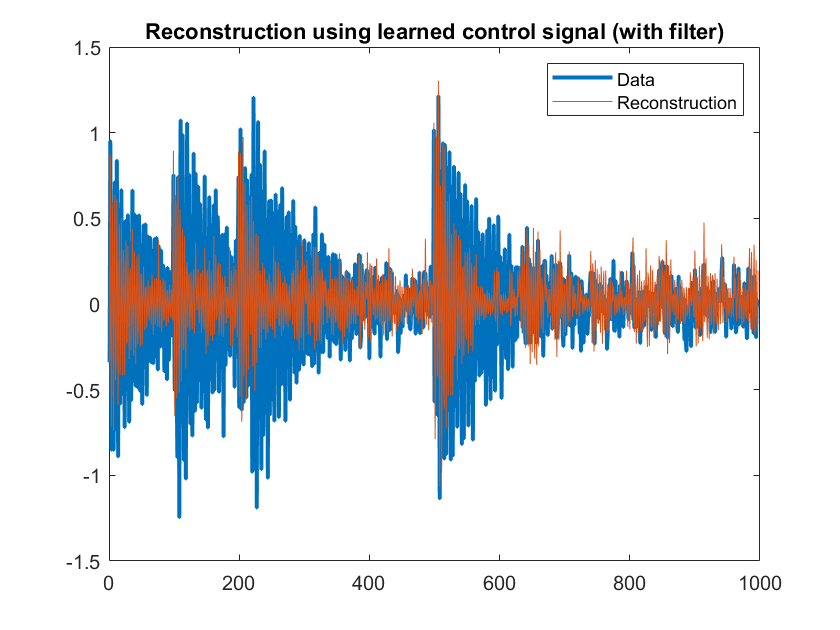


figure;
plot(X(1,:), 'linewidth', 2)
hold on
plot(learned_X2(1,:))
legend("Data", "Reconstruction")
title("Reconstruction using learned control signal (with filter)")